%function f=Obj_fun(k_firbc)
    k_firbc=1;
    d=0.6;                  %单根纤维的直径  mm 
    h=2*d;                  %织物的厚度  mm
    rho_s=0.6;                %经密6/1cm
    rho_w=0.8;                %维密8/1cm
    a=1/rho_s;           %经向长度mm
    b=1/rho_w;           %纬向长度mm
    T_end=0.1;              %
    delta_t=0.0992;         
    delta_T = 0.9709;        %299.1- 298.1;%单位 K
    A=a*b;                  %d 单位 mm^2    
    k_tol=0.033;            %热导率 W/(m·K)
    m = 0;
    x = linspace(0,h,50);   %单位 mm
    dx=(x(2)-x(1));          %单位mm
    t = linspace(0:T_end,50); %单位s
    alpha_tol=0.663; % 总扩散率 mm^2/s
    cp=0.5; %单位  Mj/m^3·K
    k_tol=0.033;  %热导率 W/(m·K)
    rho_tol=k_tol/(cp*alpha_tol);  %总密度  W/(m·K)   mm^2/s   
    k_air=0.0296;%单位 W/(m·K)
    theta_s=19.8/360*2*pi; %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi; %纬纱弯曲角度 rad


A=1e-3*2*d/k_tol/0.9709

A = 0.0375

a=10/6  %1/rho_s  

a = 1.6667

b=10/8  %1/rho_w

b = 1.2500

a*b

ans = 2.0833

(a-d)*(b-d)%空气固有

ans = 0.6933

a*b-(a-d)*(b-d) %纤维最大不超过

ans = 1.3900


 theta_s=19.8/360*2*pi;                 %经纱弯曲角度 rad
 theta_w=25.64/360*2*pi;                %纬纱弯曲
 a*tan(theta_s)-d

ans = 3.6922e-05

 b*tan(theta_w)-d

ans = -2.6999e-05

syms h 
f=2*sqrt((d/2-h)^2+(d/2)^2)*2;
y=int(f,h)

$$y = \frac{9\,\mathrm{asinh}\left(\frac{10\,h}{3}-1\right)}{50}+2\,\sqrt{{\left(h-\frac{3}{10}\right)}^{2}+\frac{9}{100}}\,\left(h-\frac{3}{10}\right)$$

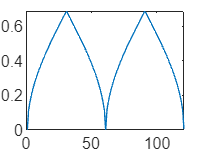

h=0:0.01:1.2;
S=[];
for i=1:length(h)
    S=[S;ca_S(h(i))];
end
plot(S)

function S=ca_S(h)
    d=0.6;
    if h>d
        h=1.2-h;
    end
    theta_s=19.8/360*2*pi;                 %经纱弯曲角度 rad
    theta_w=25.64/360*2*pi;                %纬纱弯曲角度 rad
    l=sqrt((d/2)^2-(d/2-h)^2);           %弦长
    thetas=asin(l/(d/2));
    S_s=pi*(d/2)^2*thetas/2/pi;
    thetaw=asin(l/(d/2));
    S_w=pi*(d/2)^2*thetaw/2/pi;
    S=2*(S_w/tan(theta_w)+S_s/tan(theta_s));
end